Filter Specifications

180422U

Ap = 0.07;
Aa = 47;
wp1 = 500;
wp2 = 900;
wa1 = 350;
wa2 = 1000;
ws = 2400;

Bt=min((wp1-wa1),(wa2-wp2));
wc1 = wp1-Bt/2;
wc2 = wp2+Bt/2;
T=2*pi/ws;

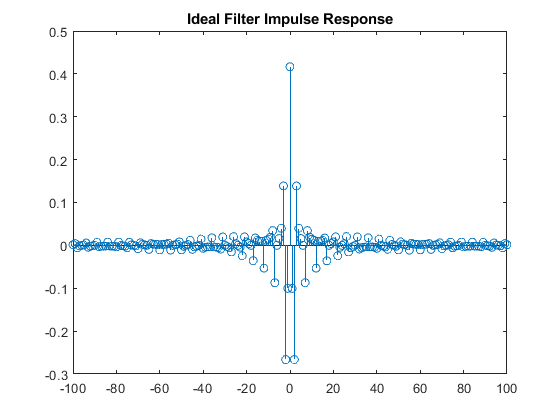

n = -100:100;
idealF = hnT(n,wc1,wc2,ws,T);
figure;
stem(n,idealF);
title('Ideal Filter Impulse Response')

deltaP=(10^(Ap/20)-1)/(10^(Ap/20)+1);
deltaA=10^(Aa/20);
delta=min(deltaP,deltaA);
ASBAtten = -20*log10(delta);
alpha=getAlpha(ASBAtten);
D= getD(ASBAtten);

N = ceil(ws*D/Bt+1);
if(mod(N,2)==0)
 N=N+1;
end
M=N-1;
tou=M/2;

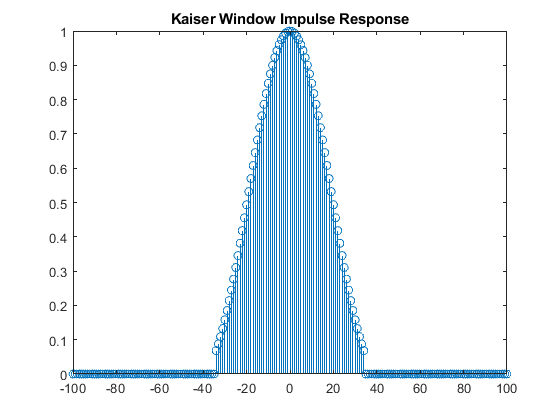

kw=kaiserWindow(n,alpha,tou,N);
stem(n,kw);
title('Kaiser Window Impulse Response')

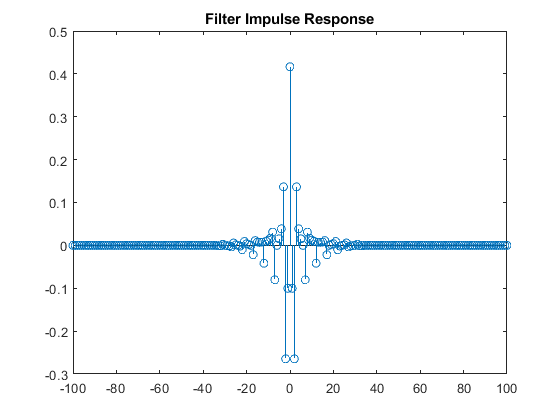

hn=idealF.*kw;
stem(n,hn);
title('Filter Impulse Response')

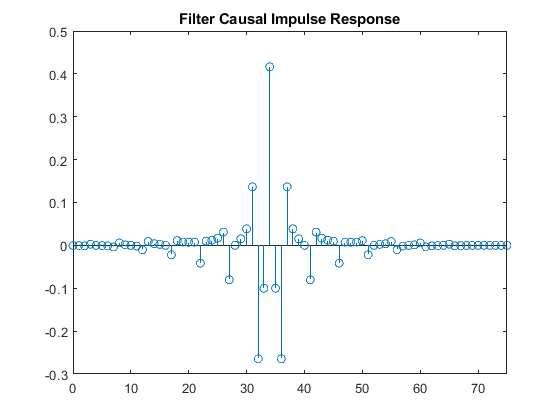

n1=n+tou;
stem(n1,hn);
xlim([0,75]);
title('Filter Causal Impulse Response')

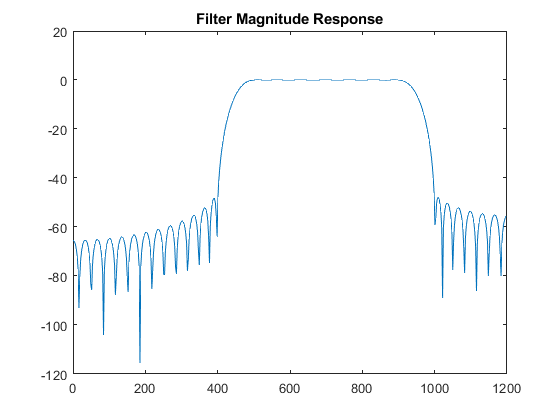

[h,w]=freqz(hn);
w=w/T;
h=20*log10(abs(h));
plot(w,h);
title('Filter Magnitude Response')

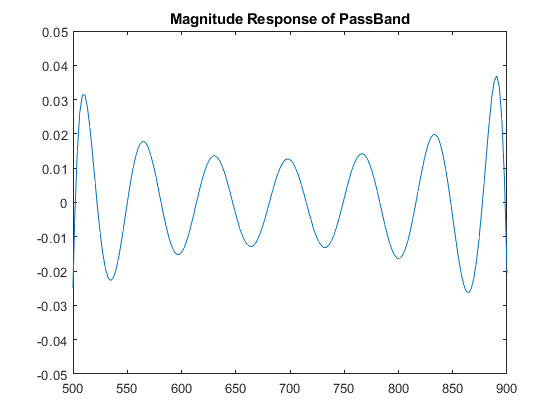

l1=round(length(w)/(ws/2)*wc1);
l2=round(length(w)/(ws/2)*wc2);
plot(w(l1:l2),h(l1:l2));
axis([wp1 wp2 -0.05 0.05]);
title('Magnitude Response of PassBand')

w1=wa1/2;
w2=(wp1+wp2)/2;
w3=(wa2+ws/2)/2;
samples=300;
n=0:1:samples;
len = 2^nextpow2(samples);
frequency = ws*(0:1/len:1/2);
xt=sin(w1*n.*T)+sin(w2*n.*T)+sin(w3*n.*T);
Xw = fft(xt,len);
Xf = T*abs(Xw(1:len/2+1));
Hw = fft(hn,len);
yt=conv(hn,xt);
Yw=fft(yt,len);
Yf=T*abs(Yw(1:len/2+1));
yExp=sin(w2*n.*T);
YwExp=fft(yExp,len);
YfExp= T*abs(YwExp(1:len/2+1));

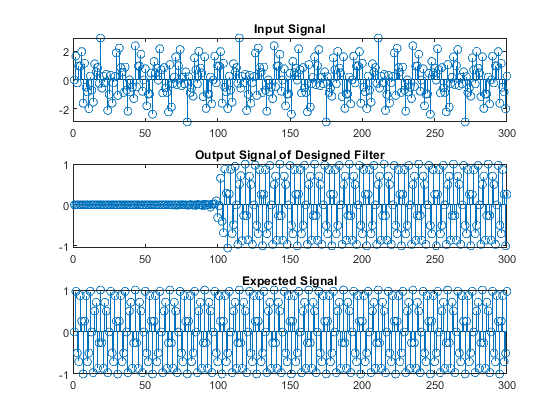

figure,
subplot(3,1,1);
t=(1:samples+1);
stem(t,xt(t));
title('Input Signal')
xlim([0,samples]);
subplot(3,1,2);
stem(t,yt(t));
title('Output Signal of Designed Filter')
xlim([0,samples]);
subplot(3,1,3);
stem(t,yExp(t));
title('Expected Signal')
xlim([0,samples]);

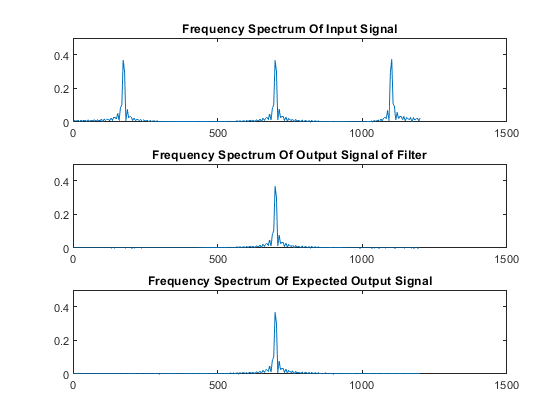

figure, 
subplot(3, 1, 1) ;
plot(frequency,Xf);
title('Frequency Spectrum Of Input Signal');
axis([0, 1500, 0, 0.5]);
subplot(3, 1, 2);
plot(frequency, abs(Yf'));
title('Frequency Spectrum Of Output Signal of Filter');
axis([0, 1500, 0, 0.5]);
subplot(3, 1, 3);
plot(frequency, abs(YfExp'));
title('Frequency Spectrum Of Expected Output Signal');
axis([0, 1500, 0, 0.5]);

Functions

function [h] = hnT(n,wc1,wc2,ws,T) 
    h=zeros(size(n));
    i1=0;
    for i = n
        i1=i1+1;
        if i==0
            h(i1)=2*(wc2-wc1)/ws;
        else
            h(i1)=(sin(wc2*i*T)-sin(wc1*i*T))/(i*pi);
        end
    end
end

%-------------------------------------------------

function [alpha] = getAlpha(ASBAtten) 
    if ASBAtten<=21
        alpha=0;
    else 
        if ASBAtten<=50
            alpha=0.5842*(ASBAtten-21)^0.4+0.07886*(ASBAtten-21);
        else
            alpha = 0.1102*(ASBAtten - 8.7);
        end
    end
end

%-------------------------------------------------

function [D]=getD(ASBAtten)
    if (ASBAtten<=21)
        D = 0.9222;
    else
        D = (ASBAtten-7.95)/14.36;
    end
end

%--------------------------------------------------

function [io]=Io(x)
    k=1;
    io=1;
    while 1
        temp=(((x/2)^k)/factorial(k))^2;
        if temp<=10e-6
            break
        end
        io=io+temp;
        k=k+1;
    end
end

%-------------------------------------------------

function [kw]=kaiserWindow(n,alpha,tou,N)
    beta=alpha*sqrt(1-(2*n/(N-1)).^2);
    kw=zeros(size(n));
    for i=1:length(n)
        if (-tou>n(i)||n(i)>tou)
            kw(i)=0;
        else
            kw(i)=Io(beta(i))/Io(alpha);
        end
    end
end